m1 = 5;
k1 = 100;
c1 = 1;

m2 = 1;
k2 = 100;
c2 = 0.1;

m3 = 10;
k3 = 40;
c3 = 0.4;

A = [0 1 0 0 0 0;
     -20 -0.2 20 0.02 0 0;
     0 0 0 1 0 0;
     20 0.2 -120 -0.12 40 0.4;
     0 0 0 0 0 1;
     0 0 100 0.1 -44 -0.44];
B = [0 0.2 0 -0.2 0 0]';
C = [1 0 1 0 0 0];
D = 0;

G = ss(A,B,C,D);

# Q3(a)

QXU = blkdiag(diag([1e2 1e-8 1e2 1e-8 1e-8 1e-8]),1e-3);
QWV = blkdiag(1e-1*eye(6),1e-3);  

K = lqg(G,QXU,QWV);

sim('MSD.slx')

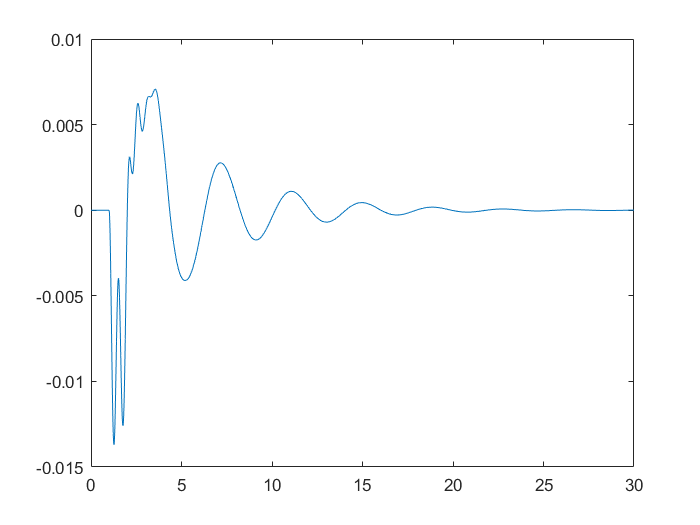

plot(simout.Time,simout.Data)

# Q3(b)

[K_inf,CL,gamma,info] = ncfsyn(G,K)

K_inf =
 
  A = 
              x1_e       x2_e       x3_e       x4_e       x5_e       x6_e          ?          ?
   x1_e     -10.21          1     -10.21          0          0          0      553.6     -528.8
   x2_e     -79.01     -21.04      34.45     -8.927      -7.53     -10.29      687.1     -656.3
   x3_e     -8.425          0     -8.425          1          0          0      456.7     -436.2
   x4_e      5.323      21.04     -208.1      8.827      47.53      10.69       3307      -3159
   x5_e    -0.6751          0    -0.6751          0          0          1      36.59     -34.95
   x6_e      69.08          0      169.1        0.1        -44      -0.44      -3744       3576
   ?             0          0          0          0          0          0     -1.967          1
   ?             0          0          0          0          0          0     -19.34       -0.2
   ?             0          0          0          0          0          0    -0.9226          0
   ?             0     

gamma = 1.6429

info = struct with fields:
    gopt: 1.6427
    emax: 0.6087
      Gs: [1×1 ss]
      Ks: [1×1 ss]


gamma

gamma = 1.6429

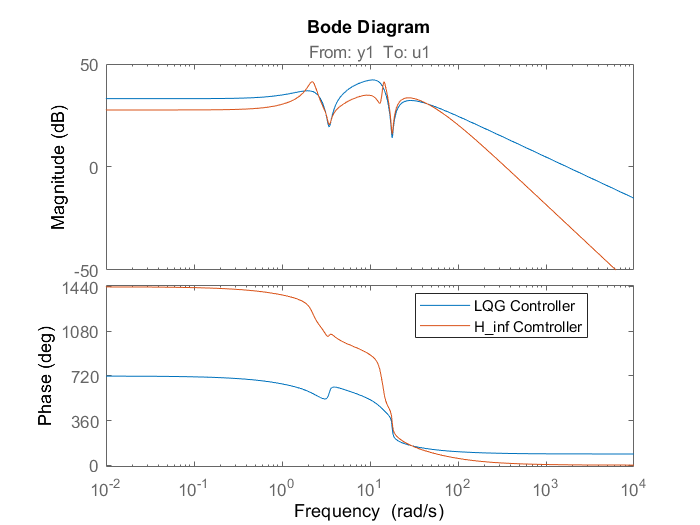

T_inf = feedback(G*K_inf,-1);
bode(K,K_inf)
legend("LQG Controller","H_inf Comtroller","Location","best")

sim('MSD_ncf.slx')

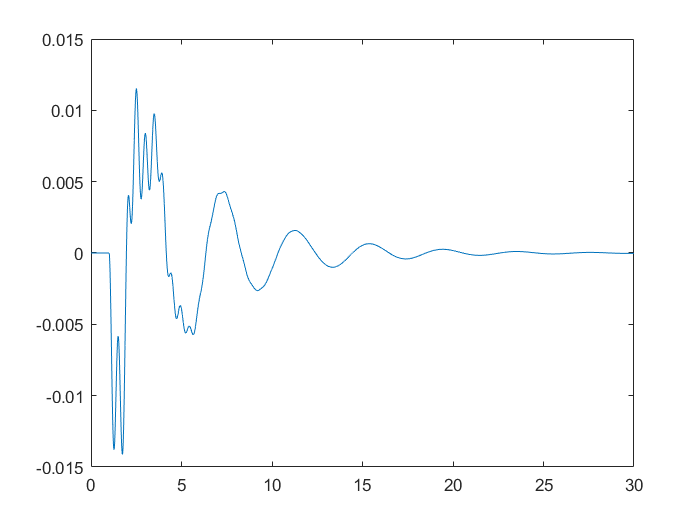

plot(simout.Time,simout.Data)

# Q3 (c)

m_2 = ureal('M2',m2,'Percentage',20);
M2 = usample(m_2,5);
data1 = [];
data2 = [];
for i = 1:5
    m2 = M2(i);
    sim('MSD.slx')
    data1(i,:) = simout.Data;
end

for i = 1:5
    m2 = M2(i);
    sim('MSD_ncf.slx')
    data2(i,:) = simout.Data;
end

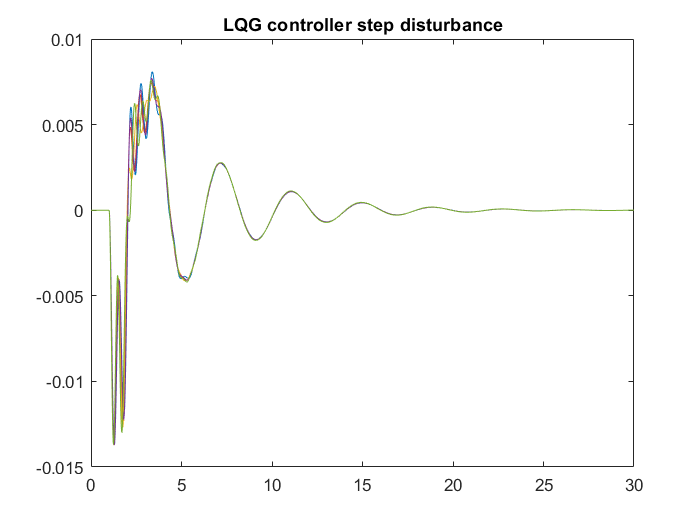

plot(simout.Time,data1)
title("LQG controller step disturbance")

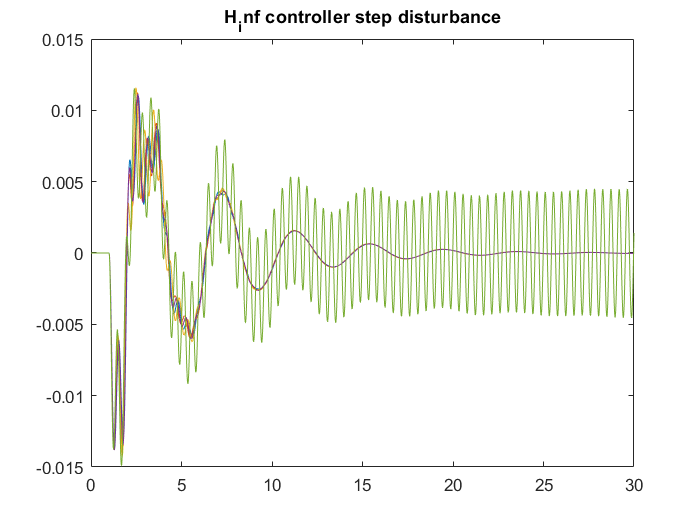

plot(simout.Time,data2)
title("H_inf controller step disturbance")